### The system:

###     $\begin{array}{l}
\dot{x_1 } =x_2 \\
\dot{x_2 } =\frac{-\textrm{fcos}x_1 -\textrm{mL}{x_2 }^2 \sin x_1 \cos x_1 +\left(M+m\right)\textrm{gsin}x_1 }{L\left(M+m\sin^2 x_1 \right)}\\
y=x_1 
\end{array}$, 

### where $m=0\ldotp 1,g=9\ldotp 81,M=1\ldotp 0,L=1$and $f$ is control law.

#### 1. Based on  input-output linearization, design a tracking controller

Since $y=x_1$, we compute its derivatives until the input $f$ appears.


$$\begin{array}{l}
\dot{y} =\dot{x_1 } =x_2 \\
\ddot{y} =\dot{x_2 } =\frac{-f\;\cos x_1 -m\;L\;{x_2 }^2 \sin x_1 \cos x_1 +\left(M+m\right)g\;\sin x_1 }{L\left(M+m\;\sin^2 x_1 \right)}
\end{array}$$


Now we define the feedback law: $\ddot{y} =v=\textrm{desired}\;\textrm{linear}\;\textrm{output}\;\textrm{dynamics}$

Set: $f=-\frac{L\left(M+m\;\sin^2 x_1 \right)v+m\;L\;\;{x_2 }^2 \;\sin x_1 \;\cos x_1 -\left(M+m\right)g\;\sin x_1 }{\cos x_1 }$

Then, define tracking law $v$: To make $y\left(t\right)\to y_d \left(t\right)$, use a second-order tracking law:

    $v=\ddot{y_d } +k_1 \dot{e} +k_0 e$, where $\begin{array}{l}
e=y-y_d \\
\dot{e} =x_2 -\dot{y_d } 
\end{array}$. Choose gains for good convergence (e.g., $k_1 =4,k_0 =4$)

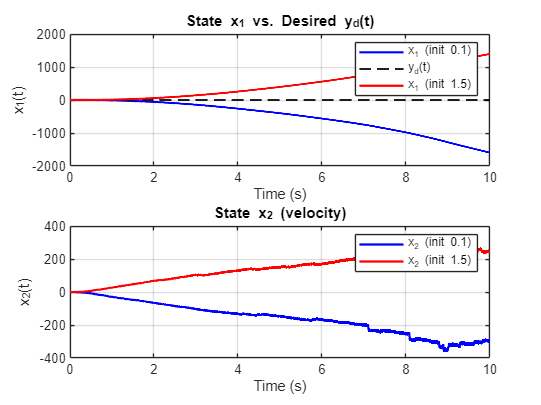

% Parameters
m = 0.1;
g = 9.81;
M = 1.0;
L = 1.0;

% Tracking controller gains (critically damped)
k0 = 4;
k1 = 4;

% Desired trajectory and derivatives
yd = @(t) cos(2*t);
dyd = @(t) -2*sin(2*t);
ddyd = @(t) -4*cos(2*t);

% System dynamics with feedback linearization
nonlinear_system = @(t, x) [
    x(2);
    compute_x2_dot(t, x, m, g, M, L, k0, k1, yd, dyd, ddyd)
];

% Compute x2_dot with control input
function dx2 = compute_x2_dot(t, x, m, g, M, L, k0, k1, yd, dyd, ddyd)
    x1 = x(1); x2 = x(2);
    e = x1 - yd(t);
    de = x2 - dyd(t);
    v = ddyd(t) + k1*de + k0*e;

    cosx1 = max(min(cos(x1), 0.5), -0.5);  % Clamp to avoid exploding division


    % Feedback linearized control law
    f = (-L*(M + m*sin(x1)^2)*v - m*L*x2^2*sin(x1)*cosx1 + (M + m)*g*sin(x1)) / cosx1;
    f = max(min(f, 100), -100);  % Saturate to ±100 for stability

    % Second state derivative
    dx2 = (-f*cosx1 - m*L*x2^2*sin(x1)*cosx1 + (M + m)*g*sin(x1)) / (L*(M + m*sin(x1)^2));
end

% Simulation time
tspan = [0 10];

% Initial states
x0_1 = [0.1; 0];    % Initial state 1
x0_2 = [1.5; 0];    % Initial state 2

% Simulate both
[t1, x1] = ode45(nonlinear_system, tspan, x0_1);
[t2, x2] = ode45(nonlinear_system, tspan, x0_2);

figure;
subplot(2,1,1);
plot(t1, x1(:,1), 'b', 'LineWidth', 1.5); hold on;
plot(t1, yd(t1), 'k--', 'LineWidth', 1.2);
plot(t2, x2(:,1), 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('x_1(t)');
title('State x_1 vs. Desired y_d(t)');
legend('x_1 (init 0.1)', 'y_d(t)', 'x_1 (init 1.5)');
grid on;

subplot(2,1,2);
plot(t1, x1(:,2), 'b', 'LineWidth', 1.5); hold on;
plot(t2, x2(:,2), 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('x_2(t)');
title('State x_2 (velocity)');
legend('x_2 (init 0.1)', 'x_2 (init 1.5)');
grid on;

- State $x_1 \left(t\right)\;$ is diverging instead of tracking the reference $y_d \left(t\right)=\cos \left(2t\right)$.

- State $x_2 \left(t\right)$ is growing liearly and not stabilizing.

### 2. Assume f=0 and sampling step=0.01 seconds. Based on Koopman theory,

### complete the following tasks.

System with $f=0$, given dynamics:$\left\lbrace \begin{array}{ll}
\dot{x_1 } =x_2  & \\
\dot{x_2 } =\frac{-m\;L\;{x_2 }^2 \sin x_1 \;\cos x_1 +\left(M+m\right)g\;\sin x_1 }{L\left(M+m\;\sin^2 x_1 \right)} & 
\end{array}\right.$

with: $\begin{array}{l}
m=0\ldotp 1,M=1\ldotp 0,L=1\ldotp 0,g=9\ldotp 81\\
\textrm{Time}\;\textrm{step}:0\ldotp 01s\\
f=0,\textrm{so}\;\textrm{no}\;\textrm{control}\;\textrm{input}
\end{array}$

#### 2.1 Find the observable function

To find the observable function, we need to lift the system into a higher-dimensional space:

    
$$g\left(x\right)=\left\lbrack x_1 ,x_2 ,\sin \left(x_1 \right),\cos \left(x_1 \right),{x_2 }^2 \right\rbrack$$


%% 2.1 - Define Observable Function
g = @(x) [x(1); x(2); sin(x(1)); cos(x(1)); x(2)^2];

#### 2.2 Find Koopman Operator

Using state transition data:

- Simulate trajectory over time (5 seconds, 0.01s step$\to$500steps)

- For each time $t_k$, compute:$\begin{array}{l}
z_k =g\left(x_k \right)\\
z_{k+1} =g\left(x_{k+1} \right)
\end{array}$

- Construct matrices:$\begin{array}{l}
Z=\left\lbrack z_0 ,z_1 ,\ldotp \ldotp \ldotp ,z_{N-1} \right\rbrack \\
\dot{Z} =\left\lbrack z_1 ,z_1 ,\ldotp \ldotp \ldotp ,z_N \right\rbrack 
\end{array}$

- Solve: $K=\dot{Z} \cdot Z_{\textrm{pseudoinverse}}$

%% 2.2 - Simulate System and Compute Koopman Operator
% System Parameters
m = 0.1; g_const = 9.81; M = 1.0; L = 1.0;
dt = 0.01; T = 5; N = T / dt;

% Define dynamics with f = 0
f = @(t, x) [
    x(2);
    (- m * L * x(2)^2 * sin(x(1)) * cos(x(1)) + (M + m) * g_const * sin(x(1))) / (L * (M + m * sin(x(1))^2))
];

% Simulate trajectory for initial state x0 = [0.1; 0]
x0 = [0.1; 0];
x = zeros(2, N+1); x(:,1) = x0;

for k = 1:N
    x(:,k+1) = x(:,k) + dt * f((k-1)*dt, x(:,k));
end

% Build snapshot matrices Z and Z_next
z_dim = 5;
Z = zeros(z_dim, N);
Z_next = zeros(z_dim, N);
for k = 1:N
    Z(:,k) = g(x(:,k));
    Z_next(:,k) = g(x(:,k+1));
end

% Compute Koopman operator
K = Z_next * pinv(Z);

#### 2.3 Koopman Prediction and Plotting

Using: $z_{k+1}^{\textrm{pred}} =Kz_k$. Then recover approximate $x_k$ by inverse mapping (e.g., from first two entries of $g\left(x\right)$).

Plot: Actual $x_1 \left(t\right),x_2 \left(t\right)$, Predicted $x_1^{\textrm{koop}} ,x_2^{\textrm{koop}}$

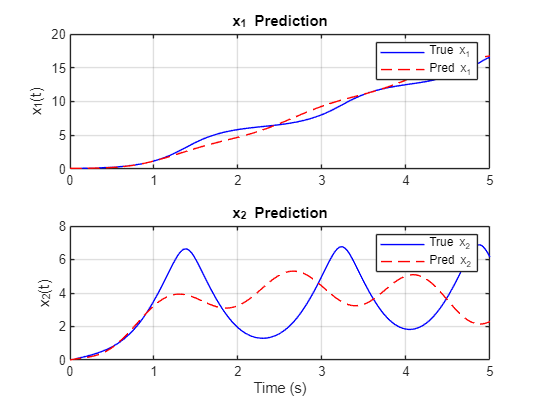

%% 2.3 - Koopman Prediction and Plotting
% Predict from initial observable
z_pred = zeros(z_dim, N+1);
x_pred = zeros(2, N+1);
z_pred(:,1) = g(x0);
x_pred(:,1) = x0;

for k = 1:N
    z_pred(:,k+1) = K * z_pred(:,k);
    x_pred(:,k+1) = z_pred(1:2,k+1); % Approximate inverse
end

t = 0:dt:T;
figure;
subplot(2,1,1);
plot(t, x(1,:), 'b', 'DisplayName','True x_1'); hold on;
plot(t, x_pred(1,:), 'r--', 'DisplayName','Pred x_1');
ylabel('x_1(t)'); legend; title('x_1 Prediction'); grid on;

subplot(2,1,2);
plot(t, x(2,:), 'b', 'DisplayName','True x_2'); hold on;
plot(t, x_pred(2,:), 'r--', 'DisplayName','Pred x_2');
ylabel('x_2(t)'); xlabel('Time (s)'); legend; title('x_2 Prediction'); grid on;

#### 2.4 Compute RMSE

$\textrm{RMSE}=\sqrt{\frac{1}{T}\sum_{k=1}^T {\left\|x_k -\hat{x_k } \right\|}^2 }$. Implement this for both initial conditions.

%% 2.4 - RMSE Calculation
rmse_x1 = sqrt(mean((x(1,:) - x_pred(1,:)).^2));
rmse_x2 = sqrt(mean((x(2,:) - x_pred(2,:)).^2));

fprintf('RMSE for x1: %.4f\n', rmse_x1);

RMSE for x1: 0.8531


fprintf('RMSE for x2: %.4f\n', rmse_x2);

RMSE for x2: 2.1717


#### 2.5 Try a New Observable Function and Re-Do

Try a different observable set with cross-terms and more nonlinear features:

    
$$g_{\textrm{new}} \left(x\right)=\left\lbrack x_1 ,x_2 ,{x_1 }^2 ,\;{x_2 }^2 ,x_1 x_2 ,\sin \left(x_1 \right)\right\rbrack$$


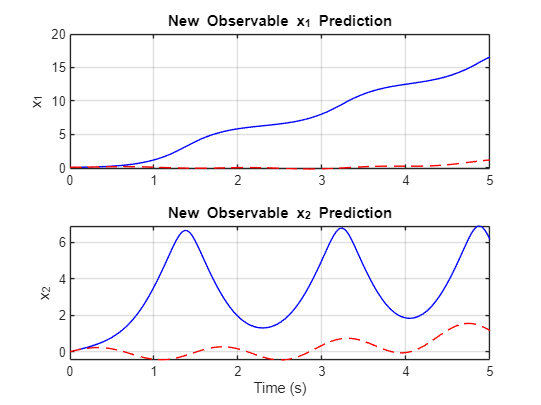

%% 2.5 - Try New Observable Function and Recompute
% New observable function
g_new = @(x) [x(1); x(2); x(1)^2; x(2)^2; x(1)*x(2); sin(x(1))];

% Regenerate Z and Z_next with new g_new
z_dim_new = 6;
Z_new = zeros(z_dim_new, N);
Z_next_new = zeros(z_dim_new, N);
for k = 1:N
    Z_new(:,k) = g_new(x(:,k));
    Z_next_new(:,k) = g_new(x(:,k+1));
end

K_new = Z_next_new * pinv(Z_new);

% Prediction
z_pred_new = zeros(z_dim_new, N+1);
x_pred_new = zeros(2, N+1);
z_pred_new(:,1) = g_new(x0);
x_pred_new(:,1) = x0;

for k = 1:N
    z_pred_new(:,k+1) = K_new * z_pred_new(:,k);
    x_pred_new(:,k+1) = z_pred_new(1:2,k+1);
end

% Plot
figure;
subplot(2,1,1);
plot(t, x(1,:), 'b', t, x_pred_new(1,:), 'r--');
title('New Observable x_1 Prediction'); ylabel('x_1'); grid on;

subplot(2,1,2);
plot(t, x(2,:), 'b', t, x_pred_new(2,:), 'r--');
title('New Observable x_2 Prediction'); ylabel('x_2'); xlabel('Time (s)'); grid on;


% RMSE
rmse_x1_new = sqrt(mean((x(1,:) - x_pred_new(1,:)).^2));
rmse_x2_new = sqrt(mean((x(2,:) - x_pred_new(2,:)).^2));

fprintf('New RMSE for x1: %.4f\n', rmse_x1_new);

New RMSE for x1: 8.4705


fprintf('New RMSE for x2: %.4f\n', rmse_x2_new);

New RMSE for x2: 3.5889


Using artificial intelligence models: 50%